## Supplementary information

## "Stability and selective extinction in complex mutualistic networks"

Hyun Woo Lee, Jae Woo Lee,Deok-Sun Lee, 

ArXiv:2106.07206 (2021), under review in Physical Review E

- A sample code for computing numerically and theoretically the stationary-state abundance of individual species governed by the Lotka-Volterra equation in Eqs. (1) and (2)  for the selected community (Ref. [35]) with c=0.1 and \tilde {m}=0.8. See the main text for more details. 

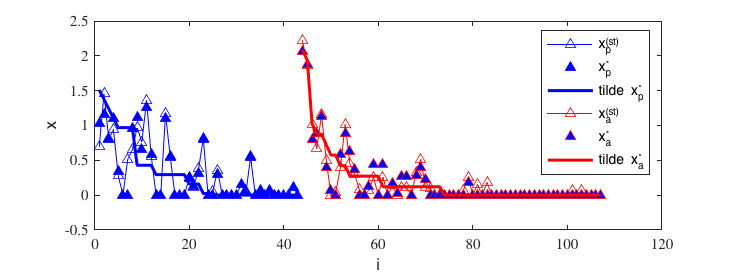

c = 0.1;  % competition strength
tm = 0.8; % \tilde{m}=0.8
A = logical(importdata('A_1.csv')); % The network in Ref. [35]
[NP NA] = size(A);  % Number of plant and animal species
N = [NP NA];
tc = (c*N)./(c*N+1-c); %\tilde{c}^{(P,A)}  
h = heterogeneitycompute(A,c); % h of the relation tm = m * h / (1-c)
m = tm*(1-c)/h;

Tmax = 1000;  % time period 0<= t <= Tmax
ExtinctTh = 1e-5;  % species i is extinct if x_i< ExtinctTh

% Stationary-state abundance of individual species %%%%%%%%%%%%%%%%%%%%%

X = LVstationary6(A,c,m,Tmax,ExtinctTh);

% X is a 6 x S matrix containing various results 

% X(1,1:S) : x_i^{(st)} for i=1,2,...,S
% X(2,1:S) : x_i^*=  -\sum_j B^{-1}_{ij} with S^0=empty 
% X(3,1:S) : x_i^*=  -\sum_{j\in S^+} B^{-1}_{ij} with S^0 from the
% algorithm in Sec. V B

% X(4,1:S) : \tilde{x}_i^{(st)} for i=1,2,...,S (from \tilde{B} in the
% annealed approximation)
% X(5,1:S) : \tilde{x}_i^*=  -\sum_j \tilde{B}^{-1}_{ij} with S^0=empty 
% X(6,1:S) : \tilde{x}_i^*=  -\sum_{j\in S^+} \tilde{B}^{-1}_{ij} with S^0
% from the algorithm in Sec. V B
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure;%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
set(gcf,'units','pixels','Position',[0 0 1120 420]);
colorcell={{rgb('ForestGreen'),rgb('RoyalBlue')},...
    {rgb('FireBrick'),rgb('Chocolate')}};
markercell={{'^-','^','-'},{'o-','o','-'}};

rowcell = {1:NP, NP+(1:NA)};

% Plants
col = 1:NP;
plot(col,X(1,col),'b^-'); hold on;
plot(col,X(3,col),'b^','markerfacecolor','b'); hold on;
plot(col,X(6,col),'b-','linewidth',2); hold on;

% Animals
col = NP + (1:NA);
plot(col,X(1,col),'r^-'); hold on;
plot(col,X(3,col),'r^','markerfacecolor','b'); hold on;
plot(col,X(6,col),'r-','linewidth',2); hold on;

%set(gca,'fontsize',labelsize,'fontname','Times','box','off');
xlabel('i');
ylabel('x');
legend('x_p^{(st)}','x_p^*','tilde x_p^*','x_a^{(st)}','x_a^*','tilde x_a^*');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

